# Distributed Coding Live Script - Single Trial All Neurons

## Setup

### MatNWB

Start by setting up your MATLAB workspace. The code below clones the MatNWB repo to the current directory and adds the folder ontaining the MatNWB package to the MATLAB search path. MatNWB works by automatically creating API classes based on a defined schema. Running the generateCore() function generates these classes for the lastest schema version.

!git clone https://github.com/NeurodataWithoutBorders/matnwb.git
cd ../matnwb
addpath(genpath(pwd));
generateCore();
cd ..

### DANDIset

Download the relevant [DANDIset](https://dandiarchive.org/dandiset/000017/draft)

## Load in file

% path to file, change to desired file
DANDIset_folder = '~/DANDIsets/000017/';
filepath = [DANDIset_folder 'sub-Moniz/sub-Moniz_ses-20170515T120000.nwb'];
% read in file
nwb_file = nwbRead(filepath);
% display number of trials
ntrials = length(nwb_file.intervals_trials.start_time.data(:));
fprintf('Total trials: %d\n', ntrials)

Total trials: 247


## Plot trial details and response

% Select trial
trial = 20;

% print trial info
infoTable = getTrialInfo(nwb_file, trial)

infoTable = 1×5 table
    Contrast Left    Contrast Right    Animal Choice     Feedback     Reaction Time
    _____________    ______________    _____________    __________    _____________

         0.5               1             {'Right'}      {'Reward'}       1.0338    


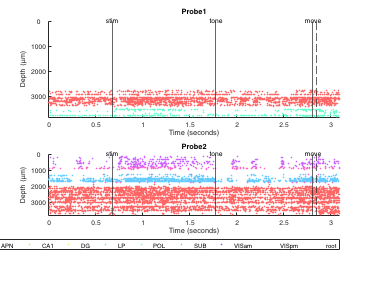

% output raster plot figure
 
plotRastersAllUnits(nwb_file, trial)